
ParentDir = "E:\YuLab\Work\GPS\Data";
TaskDir = uigetdir(ParentDir, "Choose task directionory");

ProgressClassFile = dir(TaskDir+"\*ProgressClass*.mat");
if length(ProgressClassFile)>1
    fprintf("More than one ProgressClass found");
    return;
end

load(fullfile(TaskDir, ProgressClassFile.name));


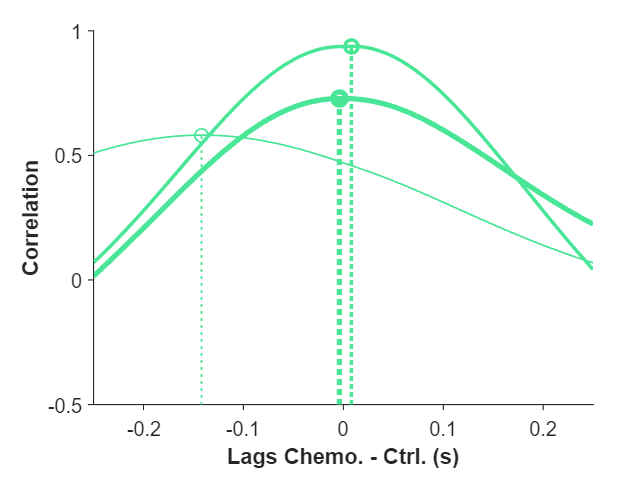

xcor     = cell(3, 2);
lags     = cell(3, 2);
cor      = zeros(3, 2);
xcor_max = zeros(3, 2);
lag_max  = zeros(3, 2);
div      = zeros(3, 2);

for j = 1:2

    fig_xcor = figure(41); clf(41);
    set(fig_xcor, 'Units', 'Centimeters', 'Position', [2 2 10 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

    ax_xcor = axes;
    set(ax_xcor, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    for i = 1:3

        hd_chemo   = obj.HDSortedChemo{i, j};
        hd_control = obj.HDSortedControl{i, j};
        hd_chemo_pdf   = ksdensity(hd_chemo,   obj.Bins.HoldDuration, 'Function', 'pdf');
        hd_control_pdf = ksdensity(hd_control, obj.Bins.HoldDuration, 'Function', 'pdf');

        div(i, j) = cal_div_kl(hd_chemo_pdf, hd_control_pdf);

        cor(i, j) = corr(hd_chemo_pdf', hd_control_pdf');

        [xcor{i, j}, lags{i, j}] = xcorr(zscore(hd_control_pdf), zscore(hd_chemo_pdf), 0.25 / obj.Bins.width, 'unbiased');
%         xcor{i, j} = xcor{i, j} / (length(hd_control_pdf)-1);

        [xcor_max(i, j), id_max] = max(xcor{i, j});
        lag_max(i, j) = lags{i, j}(id_max) * obj.Bins.width;

        plot(ax_xcor, lags{i, j}*obj.Bins.width, xcor{i, j}, 'LineWidth', 0.8*i, 'Color', GPSColor.("Port"+obj.Ports(j)))
        plot(ax_xcor, [lag_max(i, j) lag_max(i, j)], [-.5 xcor_max(i, j)], 'LineStyle', ':', 'LineWidth', 0.8*i, 'Color', GPSColor.("Port"+obj.Ports(j)))
        scatter(ax_xcor, lag_max(i, j), xcor_max(i, j), 36, GPSColor.("Port"+obj.Ports(j)), 'LineWidth', 0.8*i, 'Marker', 'o')

    end
    
    ax_xcor.XLabel.String = "Lags Chemo. - Ctrl. (s)";
    ax_xcor.XLabel.FontWeight = "bold";
    ax_xcor.YLabel.String = "Correlation";
    ax_xcor.YLabel.FontWeight = "bold";

    set(ax_xcor, 'XLim', [-.25 .25], 'YLim', [-.5 1]);

    save_name = "XCorr_Port" + obj.Ports(j) + "_" + obj.Subject + ".jpg";
    save_path = fullfile(TaskDir, save_name);
    saveas(fig_xcor, save_path);

end

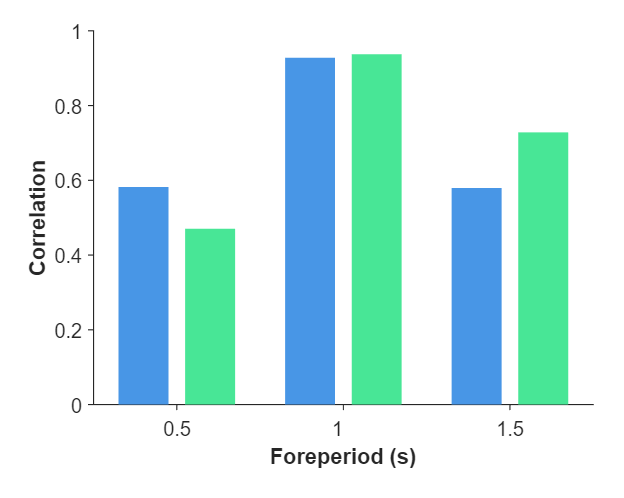

fig_corr = figure(42); clf(42);
set(fig_corr, 'Units', 'Centimeters', 'Position', [2 2 10 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_corr = axes;
set(ax_corr, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

for i = 1:2
    bar(ax_corr, (1:3)+0.2*(-1)^i, cor(:, i), 0.3, 'FaceColor', GPSColor.("Port"+obj.Ports(i)), 'EdgeColor', 'none');
end

ax_corr.XLabel.String = "Foreperiod (s)";
ax_corr.XLabel.FontWeight = "bold";
ax_corr.YLabel.String = "Correlation";
ax_corr.YLabel.FontWeight = "bold";

set(ax_corr, 'XLim', [0.5 3.5], 'YLim', [0 1], 'XTick', 1:3, 'XTickLabel', .5:.5:1.5);

save_name = "Corr_" + obj.Subject + ".jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_corr, save_path);

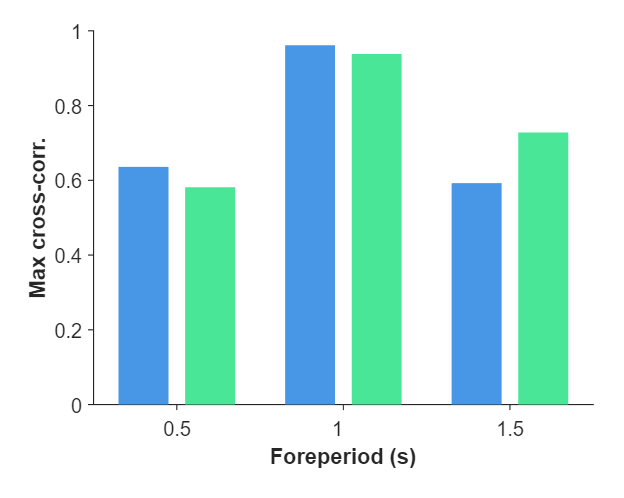


fig_xcor_max = figure(43); clf(43);
set(fig_xcor_max, 'Units', 'Centimeters', 'Position', [2 2 10 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_xcor_max = axes;
set(ax_xcor_max, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

for i = 1:2
    bar(ax_xcor_max, (1:3)+0.2*(-1)^i, xcor_max(:, i), 0.3, 'FaceColor', GPSColor.("Port"+obj.Ports(i)), 'EdgeColor', 'none');
end

ax_xcor_max.XLabel.String = "Foreperiod (s)";
ax_xcor_max.XLabel.FontWeight = "bold";
ax_xcor_max.YLabel.String = "Max cross-corr.";
ax_xcor_max.YLabel.FontWeight = "bold";

set(ax_xcor_max, 'XLim', [0.5 3.5], 'YLim', [0 1], 'XTick', 1:3, 'XTickLabel', .5:.5:1.5);

save_name = "max_XCor_" + obj.Subject + ".jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_xcor_max, save_path);

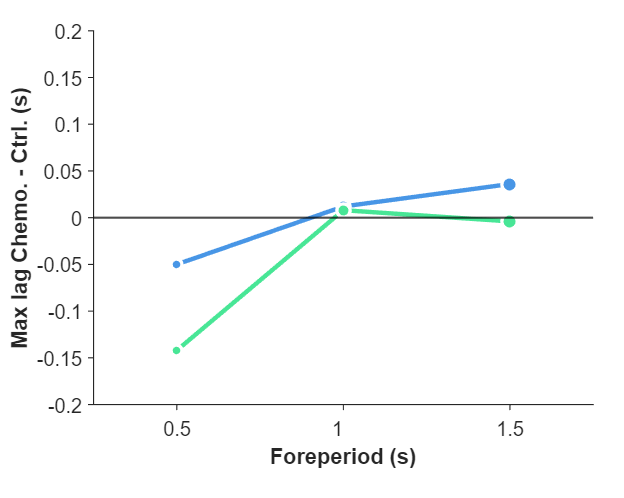


fig_lag_max = figure(44); clf(44);
set(fig_lag_max, 'Units', 'Centimeters', 'Position', [2 2 10 8], 'PaperPositionMode', 'Auto', 'Color', 'w');

ax_lag_max = axes;
set(ax_lag_max, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 6], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

yline(ax_lag_max, 0, 'LineWidth', 1, 'Color', 'k')
for i = 1:2
    plot(ax_lag_max, 1:3, lag_max(:, i), "Color", GPSColor.("Port"+obj.Ports(i)), 'LineWidth', 2);
    scatter(ax_lag_max, 1:3, lag_max(:, i), [24 36 48], 'LineWidth', 1.5, ...
        'Marker', 'o', 'MarkerFaceColor', GPSColor.("Port"+obj.Ports(i)), 'MarkerEdgeColor', 'w');
end

ax_lag_max.XLabel.String = "Foreperiod (s)";
ax_lag_max.XLabel.FontWeight = "bold";
ax_lag_max.YLabel.String = "Max lag Chemo. - Ctrl. (s)";
ax_lag_max.YLabel.FontWeight = "bold";

set(ax_lag_max, 'XLim', [0.5 3.5], 'YLim', [-.2 .2], 'XTick', 1:3, 'XTickLabel', .5:.5:1.5);

save_name = "max_Lag_" + obj.Subject + ".jpg";
save_path = fullfile(TaskDir, save_name);
saveas(fig_lag_max, save_path);

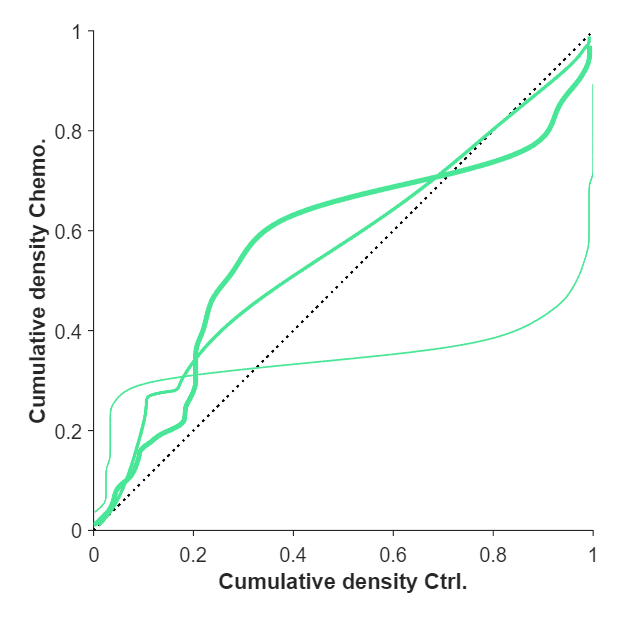


for j = 1:2

    fig_qq = figure(45); clf(45);
    set(fig_qq, 'Units', 'Centimeters', 'Position', [2 2 10 10], 'PaperPositionMode', 'Auto', 'Color', 'w');

    ax_qq = axes;
    set(ax_qq, 'Units', 'Centimeters', 'Position', [1.5 1.5 8 8], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    plot(ax_qq, [0 1], [0 1], ':k', 'LineWidth', 1);

    for i = 1:3

        hd_chemo   = obj.HDSortedChemo{i, j};
        hd_control = obj.HDSortedControl{i, j};

        hd_chemo_cdf   = ksdensity(hd_chemo,   obj.Bins.HoldDuration, 'Function', 'cdf');
        hd_control_cdf = ksdensity(hd_control, obj.Bins.HoldDuration, 'Function', 'cdf');

        plot(ax_qq, hd_control_cdf, hd_chemo_cdf, 'LineWidth', 0.8*i, 'Color', GPSColor.("Port"+obj.Ports(j)));

    end

    ax_qq.XLabel.String = "Cumulative density Ctrl.";
    ax_qq.XLabel.FontWeight = "bold";
    ax_qq.YLabel.String = "Cumulative density Chemo.";
    ax_qq.YLabel.FontWeight = "bold";

    set(ax_qq, 'XLim', [0 1], 'YLim', [0 1], 'XTick', 0:.2:1, 'YTick', 0:.2:1);

    save_name = "QQ_plot_" + obj.Ports(j) + "_" + obj.Subject + ".jpg";
    save_path = fullfile(TaskDir, save_name);
    saveas(ax_qq, save_path);

end

function div_kl = cal_div_kl(P, Q)

ind_good = P>0 & Q>0;

div_1 = sum( P(ind_good) .* (log(P(ind_good)) - log(Q(ind_good))) );
div_2 = sum( Q(ind_good) .* (log(Q(ind_good)) - log(P(ind_good))) );

div_kl = (div_1 + div_2) / 2;

end